clear ;clc;close all
%Sistem stanja
%parametri sistema
g= 9.81;%
m= 0.03;%
R= 0.04;%
J_w= m*R^2/2;%
M=0.6;%
W=0.14;
H=0.144;
L=H/2;
J_psi=M*L^2/3;
J_m=1e-5;
R_m=6.69;
K_b=0.468;
K_t=0.317;
n=1;
f_m=0.0022;
f_w=0.0001;

f_m = ureal('fm', 0.0022,'Range',[0.001,0.005])

f_m =   Uncertain real parameter "fm" with nominal value 0.0022 and range [0.001,0.005].


f_w = ureal('fw', 0.0001,'Range',[0.00005,0.0002])

f_w =   Uncertain real parameter "fw" with nominal value 0.0001 and range [5e-05,0.0002].



%prarametri e
e11=(2*m+M)*R^2+2*J_w+2*n^2*J_m;
e12=M*L*R-2*n^2*J_m;
e22=M*L*L+J_psi+2*n^2*J_m;
detE=e11*e22-e12^2;
% alfa beta sigma
alfa=n*K_t/R_m;
beta=n*K_t*K_b/R_m+f_m

beta =

  Uncertain matrix with 1 rows and 1 columns.
  The uncertainty consists of the following blocks:
    fm: Uncertain real, nominal = 0.0022, range = [0.001,0.005], 1 occurrences

Type "beta.NominalValue" to see the nominal value, "get(beta)" to see all properties, and "beta.Uncertainty" to interact with the uncertain elements.



sig=beta+f_w;
%koeficijenti matrice A
a32=-g*M*L*e12/detE;
a42= g*M*L*e11/detE;
a33=-2*(sig*e22+ beta*e12)/detE;
a43= 2*(sig*e12 + beta*e11)/detE;
a34= 2*beta*(e22+e12)/detE;
a44= -2*beta*(e11+e12)/detE;
%matrica A
A=[0 0 1 0;0 0 0 1;...
    0 a32 a33 a34;0 a42 a43 a44]

A =

  Uncertain matrix with 4 rows and 4 columns.
  The uncertainty consists of the following blocks:
    fm: Uncertain real, nominal = 0.0022, range = [0.001,0.005], 1 occurrences
    fw: Uncertain real, nominal = 0.0001, range = [5e-05,0.0002], 1 occurrences

Type "A.NominalValue" to see the nominal value, "get(A)" to see all properties, and "A.Uncertainty" to interact with the uncertain elements.



%koeficijenti matrice B
b3=alfa*(e22+e12)/detE;
b4=-alfa*(e11+e12)/detE;
%matrica B
B=[0 0;0 0;b3 b3;b4 b4]

B =          0         0
         0         0
  157.5798  157.5798
  -75.9576  -75.9576


%matrice C i D
C=[1 0 0 0;0 1 0 0;...
    0 0 1 0;0 0 0 1]

C =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


D=zeros(4,2)

D =      0     0
     0     0
     0     0
     0     0



G=minreal(ss(A,B,C,D))

G =

  Uncertain continuous-time state-space model with 4 outputs, 2 inputs, 4 states.
  The model uncertainty consists of the following blocks:
    fm: Uncertain real, nominal = 0.0022, range = [0.001,0.005], 1 occurrences
    fw: Uncertain real, nominal = 0.0001, range = [5e-05,0.0002], 1 occurrences

Type "G.NominalValue" to see the nominal value, "get(G)" to see all properties, and "G.Uncertainty" to interact with the uncertain elements.



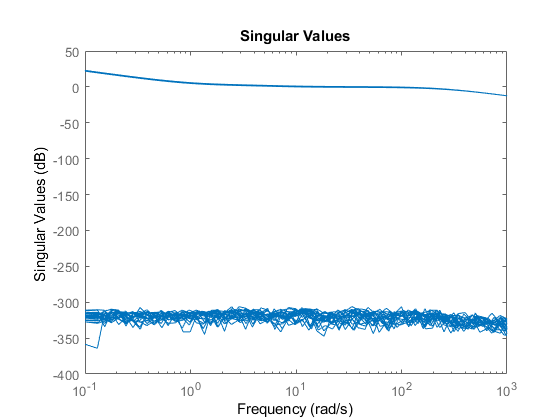

sigma(G)

%funkcije prenosa
G=tf(minreal(ss(A,B,C,D)))

G =
 
  From input 1 to output...
          157.6 s^2 + 8.398e-13 s - 1.137e04
   1:  ----------------------------------------
       s^4 + 240.7 s^3 - 264.1 s^2 - 1.174e04 s
 
                 -75.96 s - 5.364
   2:  ------------------------------------
       s^3 + 240.7 s^2 - 264.1 s - 1.174e04
 
        157.6 s^2 + 1.12e-12 s - 1.137e04
   3:  ------------------------------------
       s^3 + 240.7 s^2 - 264.1 s - 1.174e04
 
               -75.96 s^2 - 5.364 s
   4:  ------------------------------------
       s^3 + 240.7 s^2 - 264.1 s - 1.174e04
 
  From input 2 to output...
          157.6 s^2 + 8.398e-13 s - 1.137e04
   1:  ----------------------------------------
       s^4 + 240.7 s^3 - 264.1 s^2 - 1.174e04 s
 
                 -75.96 s - 5.364
   2:  ------------------------------------
       s^3 + 240.7 s^2 - 264.1 s - 1.174e04
 
        157.6 s^2 + 1.12e-12 s - 1.137e04
   3:  ------------------------------------
       s^3 + 240.7 s^2 - 264.1 s - 1.174e04
 
              

pole(G)

ans =          0
 -241.6405
    7.4312
   -6.5393
 -241.6405
    7.4312
   -6.5393
 -241.6405
    7.4312
   -6.5393


tzero(G)


ans =

  0×1 empty double column vector



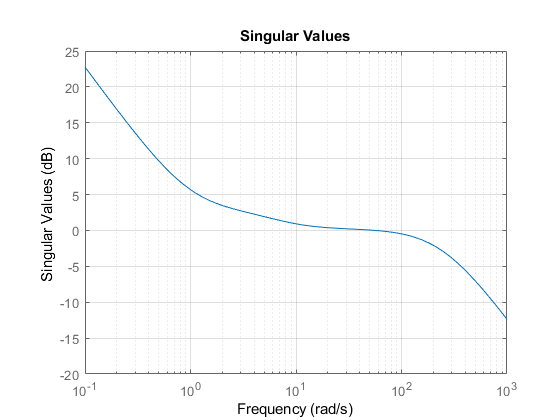

figure()
sigma(G)
ylim([-20 25])
grid on
xlim([0.1 1000])

%te

M = ss(A,B,eye(4),0)

M =

  Uncertain continuous-time state-space model with 4 outputs, 2 inputs, 4 states.
  The model uncertainty consists of the following blocks:
    fm: Uncertain real, nominal = 0.0022, range = [0.001,0.005], 1 occurrences
    fw: Uncertain real, nominal = 0.0001, range = [5e-05,0.0002], 1 occurrences

Type "M.NominalValue" to see the nominal value, "get(M)" to see all properties, and "M.Uncertainty" to interact with the uncertain elements.



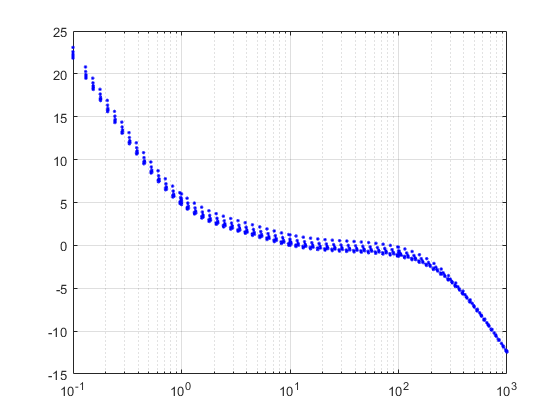

    figure;
for n=1:10
    [sig,w] = sigma(usample(M));

    semilogx(w,20*log10(sig(1,:)),'b.')
    hold on
    grid on
end


[G , D] = lftdata(M)

G =
 
  A = 
           x1      x2      x3      x4
   x1       0       0       1       0
   x2       0       0       0       1
   x3       0  -409.7  -162.6   162.1
   x4       0   269.6   78.34  -78.15
 
  B = 
            u1       u2       u3       u4
   x1        0        0        0        0
   x2        0        0        0        0
   x3   -3.773  -0.5395    157.6    157.6
   x4    1.819   0.2211   -75.96   -75.96
 
  C = 
           x1      x2      x3      x4
   y1       0       0   2.962  -2.962
   y2       0       0   0.583       0
   y3       1       0       0       0
   y4       0       1       0       0
   y5       0       0       1       0
   y6       0       0       0       1
 
  D = 
           u1      u2      u3      u4
   y1     0.4       0       0       0
   y2       0  0.3333       0       0
   y3       0       0       0       0
   y4       0       0       0       0
   y5       0       0       0       0
   y6       0       0       0       0
 
Continuous-time state-spac